# Running a Soft Constrained Optimisation with SNOBFit in MATLAB

**Barnaby Walker, James H. Bannock, Adrian M. Nightingale, and John C. de Mello**

In our article, 'Tuning Reaction Products by Constrainted Optimsation', we use the Stable Noisy Optimisation by Branch and Fit algorithm, or SNOBFit, to carry out soft constrained optimisations of a chemical synthesis. For ease of use, we developed a MATLAB class-based wrapper around the original SNOBFit code. The following tutorial will explain how to use this package to run a soft constrained optimisation.

This tutorial is designed to follow on from a more introductory one found in the **'snobfit_tutorial'** file. If you have not done so already, please start with that tutorial.

## RUNNING A SOFT CONSTRAINED OPTIMISATION

To use the package, you first need to import. If you put the package in your MATLAB folder you can do this simply by calling:

import snobfitclass.*

Otherwise, you will have to make sure that you are in the same folder as the package.

## Creating the SNOBFit Object

The class-based wrapper that we have written is based around a SNOBFit optimisation object. This object has various settings that you can change to set up your experiment, will run the actual optimisation, and will store all of your results.

The first thing you need to do to use it, is create the object:

snobfit_object = snobfitclass.snobclass('name', 'my_first_constrained_snobfit')

User must enter function and setup values!


snobfit_object =   snobclass with properties:

           name: 'my_first_constrained_snobfit'
            fcn: 'none'
        softfcn: 'none'
         linked: 0
           soft: 0
     continuing: 0
          combo: 0
         status: []
      minimised: []
          fbest: []
          xbest: []
          ncall: 100
    termination: 'minimised'


## Setting Up a Constrained Optimisation

As with the normal SNOBFit optimisation, you first need to give the object the name of the objective function to minimise:

snobfit_object.fcn = 'hsf18'

SNOBFIT experiment has been created!


snobfit_object =   snobclass with properties:

           name: 'my_first_constrained_snobfit'
            fcn: 'hsf18'
        softfcn: 'none'
         linked: 0
           soft: 1
     continuing: 0
          combo: 0
         status: 'initialised'
      minimised: 0
          fbest: []
          xbest: []
          ncall: 10000
    termination: 'minimised'


As well as an objective function, for a constrained optimisation you need to provide the name of the file containing the constraint definitions:

snobfit_object.softfcn = 'hsf18'

snobfit_object =   snobclass with properties:

           name: 'my_first_constrained_snobfit'
            fcn: 'hsf18'
        softfcn: 'hsf18'
         linked: 0
           soft: 1
     continuing: 0
          combo: 0
         status: 'initialised'
      minimised: 0
          fbest: []
          xbest: []
          ncall: 10000
    termination: 'minimised'


Although this has the same name as the objective function, they are not the same file. Constraint functions are stored in a separate folder in the package's code. For more information on this, and how to define your own function, please read the separate tutorial 'DEFINING STUFF'.

Like the normal SNOBFit optimisation, there are a number of other settings that can be customised, such as the maximum number of function calls or the termination mode:

snobfit_object.ncall = 1000;
snobfit_object.termination = 'minimised';

 For a soft constrained optimisation, it is important to set the bounds of the constraints:

snobfit_object.F1 = [0, 0]';      % the lower bounds, this problem has two constraints
snobfit_object.F2 = [Inf, Inf]';  % the upper bounds, this problem has two constraints

As well as the parameter for how hard or soft those constraints are:

snobfit_object.sigma = [1.25, 1.25]';

At this point, we can run our soft constrained SNOBFit optimisation:

SNOBFIT experiment is running...
ncall:	1 to 6
xbest:	23.184000, 3.950000
fbest:	0.092252
ncall:	7 to 12
xbest:	23.184000, 3.950000
fbest:	0.092252
ncall:	13 to 18
xbest:	23.184000, 3.950000
fbest:	0.092252
ncall:	19 to 24
xbest:	11.568000, 3.500000
fbest:	0.054185
ncall:	25 to 30
xbest:	11.568000, 3.500000
fbest:	0.054185
ncall:	31 to 36
xbest:	23.184000, 1.950000
fbest:	0.029901
ncall:	37 to 42
xbest:	23.184000, 1.950000
fbest:	0.029901
ncall:	43 to 48
xbest:	23.184000, 1.950000
fbest:	0.029901
ncall:	49 to 54
xbest:	23.184000, 1.950000
fbest:	0.029901
ncall:	55 to 60
xbest:	23.184000, 1.950000
fbest:	0.029901
ncall:	61 to 66
xbest:	23.184000, 1.950000
fbest:	0.029901
ncall:	67 to 72
xbest:	23.184000, 1.950000
fbest:	0.029901
ncall:	73 to 78
xbest:	17.376000, 2.300000
fbest:	0.024974
ncall:	79 to 84
xbest:	17.376000, 2.300000
fbest:	0.024974
ncall:	85 to 90
xbest:	17.376000, 2.300000
fbest:	0.024974
ncall:	91 to 96
xbest:	11.664000, 2.150000
fbest:	0.011521
ncall:	97 to 102
xbest:	11

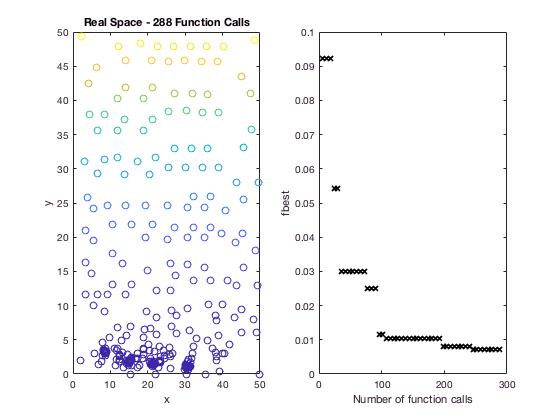

snobfit_object.startExp;

As the optimisation runs, the object prints out the current best function value and the location of that value. It also shows a scatter plot of all the points shown so far, next to a plot of the best function value against the number of function calls. This can help you to visualise your results as the optimisation proceeds, and see if everything is proceeding as it should be.

## ACCESSING YOUR RESULTS

After your optimisation has run, you can access the results directly through the SNOBFit object itself.

To see what the best function value found was:

snobfit_object.fbest

ans = 0.0072

And the location of the best point:

snobfit_object.xbest

ans =    14.7840    1.7500


You can also access the location of best point found within the constraints:

snobfit_object.xsoft

ans =    15.1680    1.6000


And the value of of the soft merit function at that point:

snobfit_object.fsoft

ans = 0.5148

You can also see all of the parameters that the optimisation tried:

snobfit_object.x

ans =     2.0160    2.0000
   30.3840   38.5500
   48.1440    8.0000
   23.1840    3.9500
   35.2320   15.5500
   13.3440   16.2000
    2.2080   49.3500
   48.4800   48.7500
   49.5360   27.9500
    3.1200   31.1000


And all of the objective function values that these gave:

snobfit_object.f

ans =    1.0e+03 *

    0.0040
    1.4953
    0.0872
    0.0210
    0.2542
    0.2642
    2.4355
    2.4001
    0.8057
    0.9673


All of the constraint function values:

snobfit_object.F

ans =    1.0e+03 *

   -0.0210   -0.0169
    1.1463    2.3843
    0.3602    2.3568
    0.0666    0.5281
    0.5229    1.4581
    0.1912    0.4155
    0.0840    2.4153
    2.3384    4.7019
    1.3595    3.2100
    0.0720    0.9519


And all of the soft merit values:

snobfit_object.fm

ans =     1.9957
    0.8995
    0.3328
    0.0923
    0.6002
    0.6096
    0.9359
    0.9350
    0.8279
    0.8525


As before, you can also visualise this data

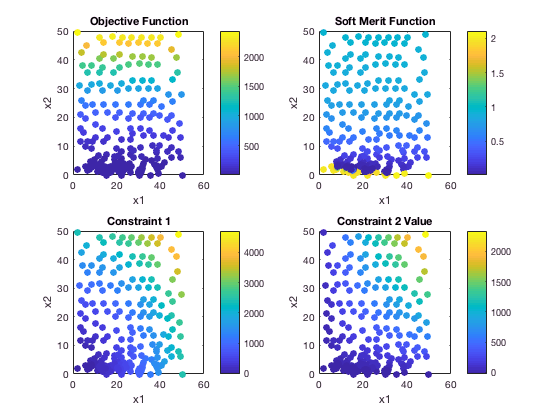

figure
subplot(221)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.f, 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Objective Function')

subplot(222)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.fm, 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Soft Merit Function')

subplot(223)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.F(:,2), 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Constraint 1')

subplot(224)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.F(:,1), 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Constraint 2 Value')

Or you can fit a surface to the data points:

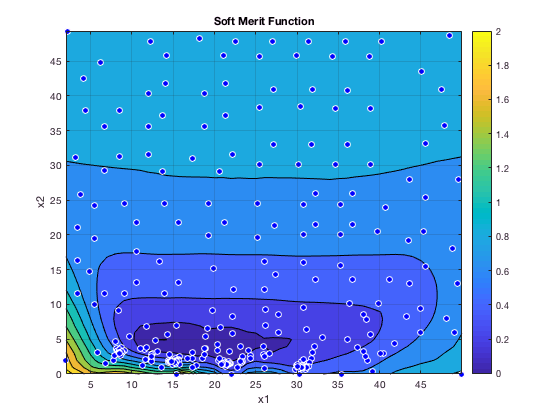

figure;
fitobject = fit(snobfit_object.x, snobfit_object.fm, 'Lowess', 'Normalize', 'on');
plot(fitobject, snobfit_object.x, snobfit_object.fm, 'Style', 'Contour');
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Soft Merit Function')

As well as storing your results on the SNOBFit object itself, the object also saves a copy of itself, along with a comma-separated file of the results and a summary of the optimisation settings, in the Results folder on the object's filepath. This means that you can back in the actual SNOBFit object to MATLAB, which is handy if you turn off your computer or want to use your results on a different computer that has MATLAB. You can also use your results in any other programming language, like Python, or analysis software, like Excel, by loading in the results CSV file.